% In this file, we tried to match similar pictures by 
% calculating the Chi Squared distance for colour 
% similarity and ssim for structure similarity.
% However, this doesn't seem to work very well with 
% pic 16 and 19.

% We might need to switch to HSV format, since the 
% picture is quite similar in the hue histogram.

cd /Users/lumizhang/Documents/GitHub/AI_B_Project_2023
clc;
clear;

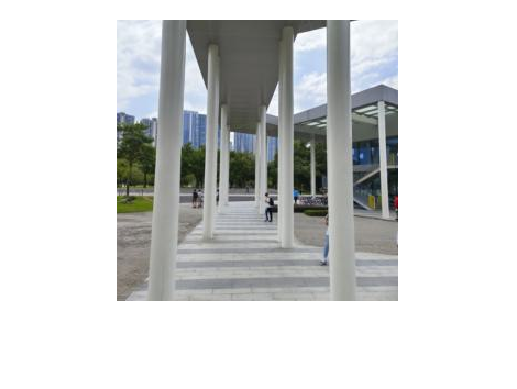

source = imread("dataset/img_256/16.jpg");
imshow(source)

checking picture number 01


Chi-squared distance is: 0.836


SSIM score is: 0.435


checking picture number 02


Chi-squared distance is: 0.355


SSIM score is: 0.398


checking picture number 03


Chi-squared distance is: 0.344


SSIM score is: 0.450


checking picture number 04


Chi-squared distance is: 1.094


SSIM score is: 0.548


checking picture number 05


Chi-squared distance is: 0.898


SSIM score is: 0.443


checking picture number 06


Chi-squared distance is: 0.414


SSIM score is: 0.442


checking picture number 07


Chi-squared distance is: 1.029


SSIM score is: 0.517


checking picture number 08


Chi-squared distance is: 0.653


SSIM score is: 0.437


checking picture number 09


Chi-squared distance is: 0.649


SSIM score is: 0.490


checking picture number 10


Chi-squared distance is: 0.873


SSIM score is: 0.512


checking picture number 11


Chi-squared distance is: 1.090


SSIM score is: 0.527


checking picture number 12


Chi-squared distance is: 0.677


SSIM score is: 0.460


checking picture number 13


Chi-squared distance is: 0.592


SSIM score is: 0.448


checking picture number 14


Chi-squared distance is: 0.442


SSIM score is: 0.448


checking picture number 15


Chi-squared distance is: 1.094


SSIM score is: 0.548


checking picture number 16


Chi-squared distance is: 0.000


SSIM score is: 1.000


Same picture at 16 


checking picture number 17


Chi-squared distance is: 1.512


SSIM score is: 0.396


checking picture number 18


Chi-squared distance is: 0.616


SSIM score is: 0.399


checking picture number 19


Chi-squared distance is: 1.117


SSIM score is: 0.487


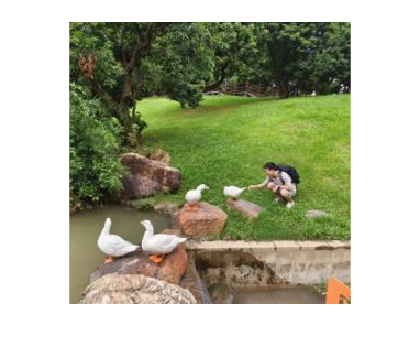

checking picture number 20


Chi-squared distance is: 0.630


SSIM score is: 0.429


close all;
debug = 1;
for i = 1:20
    fprintf("\n");
    target = imread("dataset/img_256/" + sprintf('%02d.jpg', i));
    imshow(target);
    
    % Histogram Comparison to check similarities
    %% Find similar pictures with the same colour etc.
    chi = ColorSim(source, target);

    % RGB2Grey -> Edge Detection -> SSIM index
    %% Find similar structures with same structure.
    sim = StructSim(source, target);

    if (debug == 1)
        fprintf("checking picture number %02d\n", i);
        fprintf("Chi-squared distance is: %.3f\n", chi);
        fprintf("SSIM score is: %.3f\n", sim);
    end

    if(chi < 0.3)
        if(chi < 0.1)
            fprintf("Same picture at %02d \n", i)
        else
            fprintf("Colour similarity in image %02d \n", i);
        end
    end

    if(sim < 0.3)
        fprintf("Colour similarity in image %02d \n", i);
    end

    fprintf("\n");

end

Checking Picture 16 and 19 specifically

light = imread("dataset/img_256/16.jpg");
dark = imread("dataset/img_256/19.jpg");
light_g = rgb2gray(light);
dark_g = rgb2gray(dark);
imshow(light)

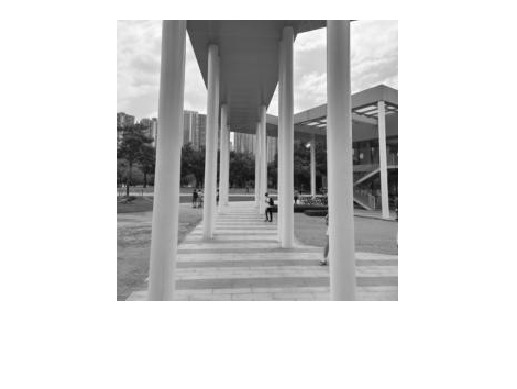

imshow(light_g);

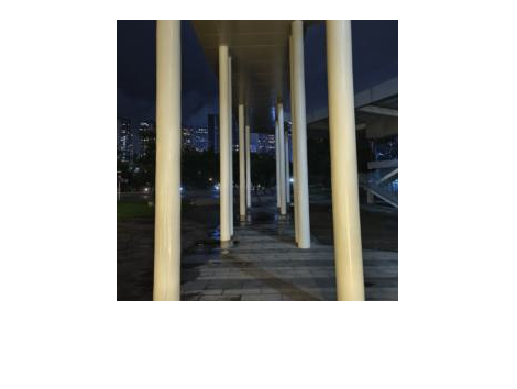

imshow(dark);

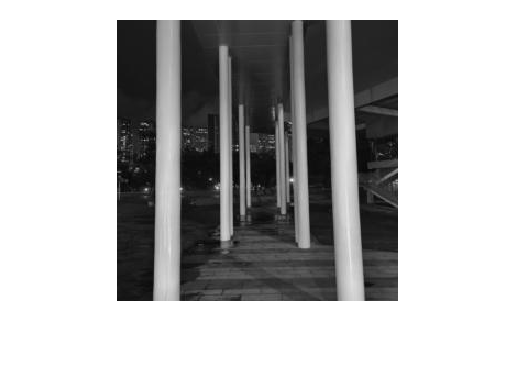

imshow(dark_g);

ssim(light, dark)

ans = 0.1751

ssim(light_g, dark_g)

ans = 0.2123

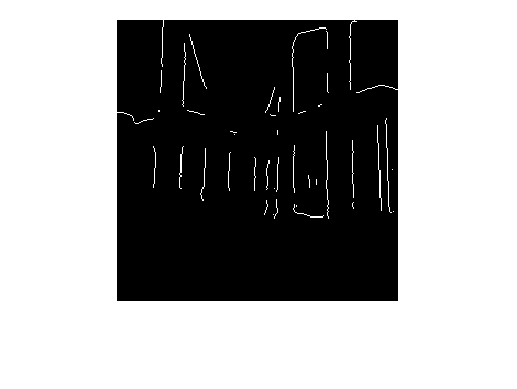

light_edge = 255*edge(imgaussfilt(light_g,3));
dark_edge = 255*edge(imgaussfilt(dark_g,3));
imshow(light_edge);

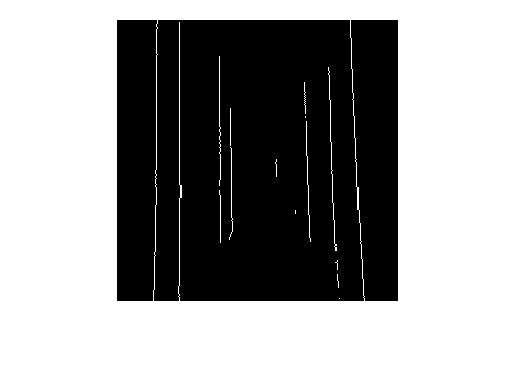

imshow(dark_edge);

ssim(light_edge, dark_edge) 

ans = 0.5759

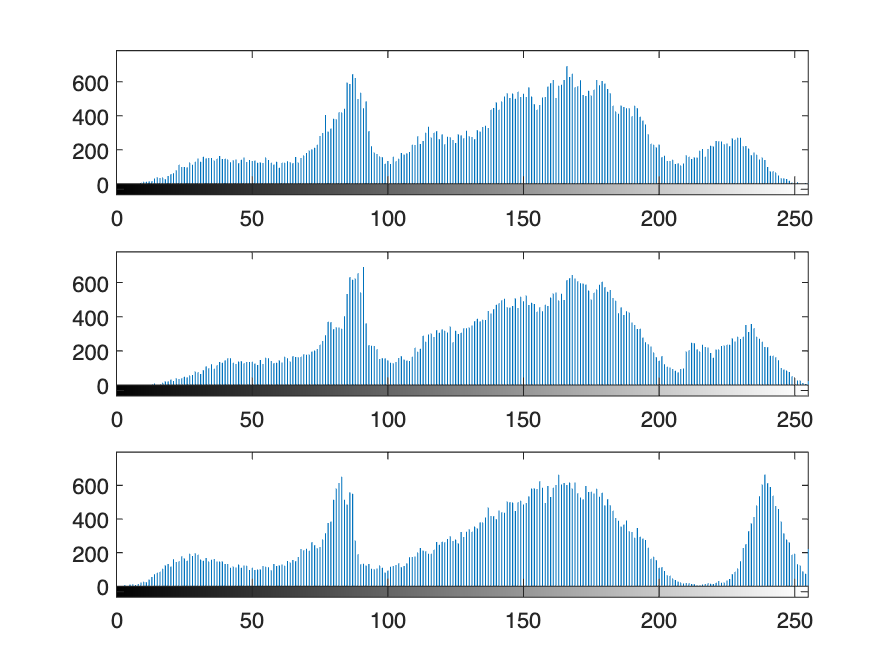

figure;
for i = 1:3
    subplot(3,1,i);
    imhist(light(:,:,i))
end

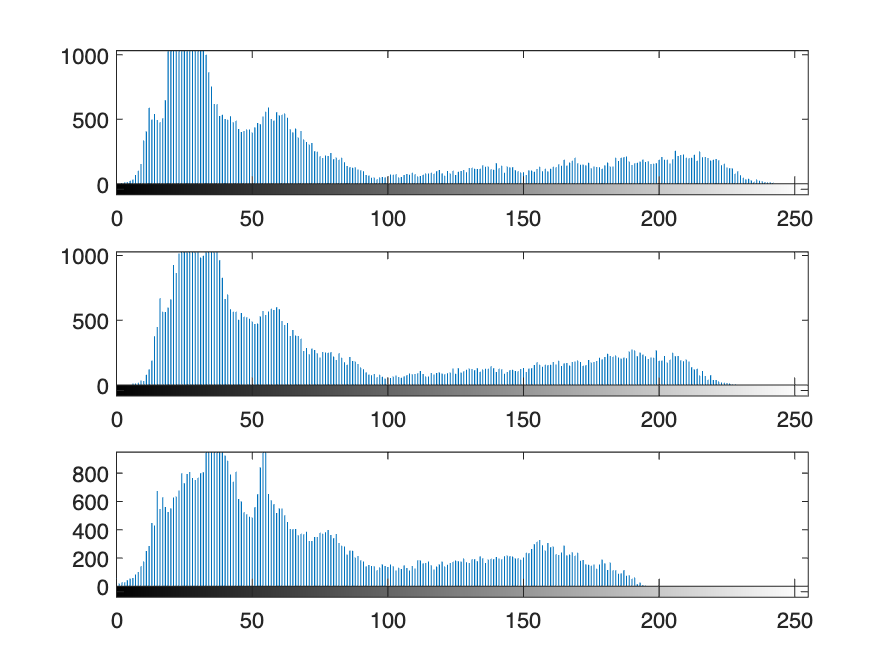


figure;
for i = 1:3
    subplot(3,1,i);
    imhist(dark(:,:,i))
end

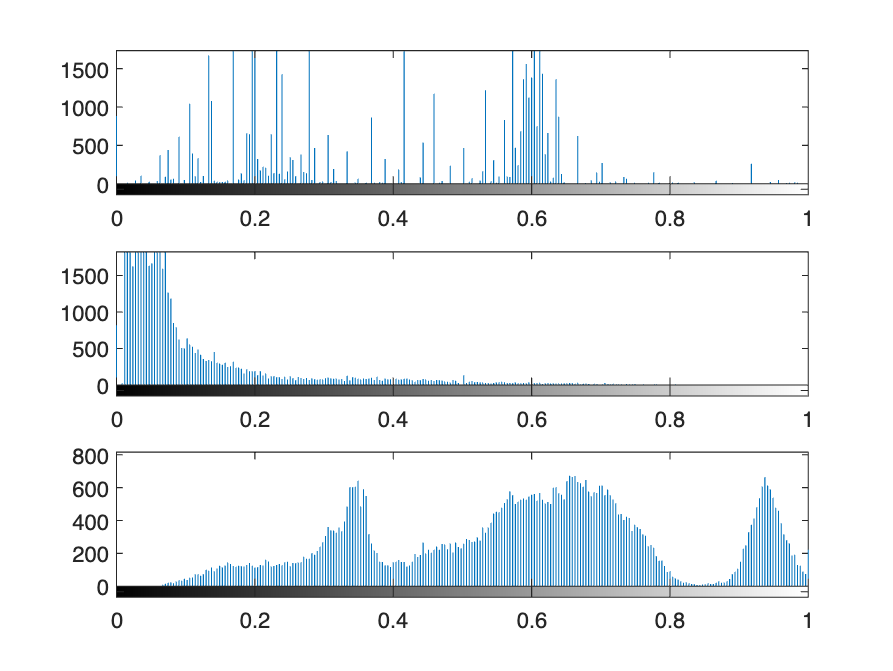


light_hsv = rgb2hsv(light);
dark_hsv = rgb2hsv(dark);
figure;
for i = 1:3
    subplot(3,1,i);
    imhist(light_hsv(:,:,i))
end

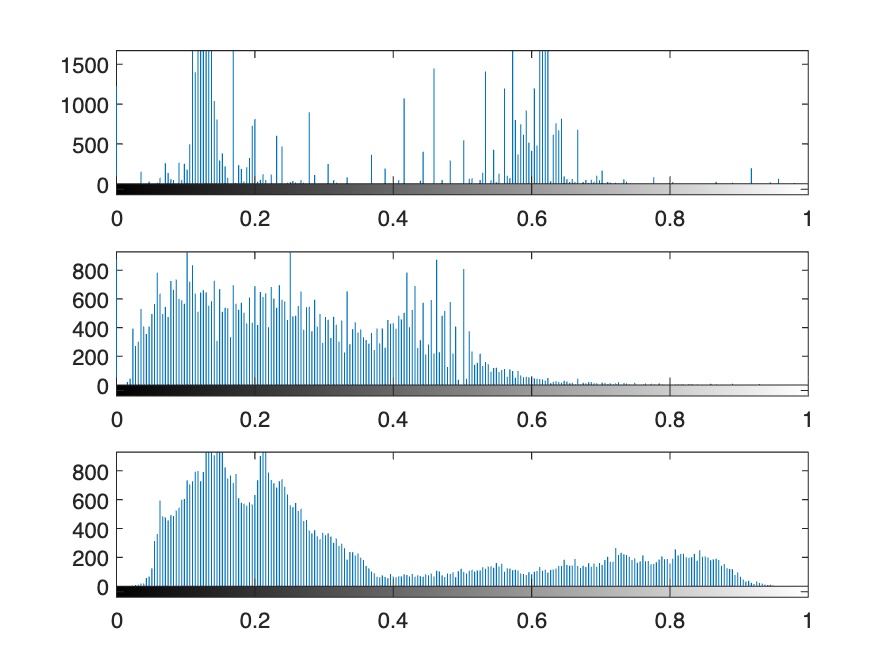


figure;
for i = 1:3
    subplot(3,1,i);
    imhist(dark_hsv(:,:,i))
end

function score = ColorSim(I1, I2)
    score = 0;
    for i=1:3
        hist1 = imhist(I1(:,:,i));
        hist2 = imhist(I2(:,:,i));
        hist1 = hist1 / sum(hist1);
        hist2 = hist2 / sum(hist2);
        chiSquaredDistance = 0.5 * sum(((hist1 - hist2).^2) ./ (hist1 + hist2 + eps));
        score = score + chiSquaredDistance;
    end
end

function score = StructSim(I1, I2)
    grey1 = imgaussfilt(rgb2gray(I1), 1.5);
    grey2 = imgaussfilt(rgb2gray(I2), 1.5);
    grey1 = 255 * edge(grey1, "sobel");
    grey2 = 255 * edge(grey2, "sobel");
    score = ssim(grey1, grey2);
end